# **Session 3: Design and implementation of PID controllers**

The practices of the Automatic Control subject consist in the study of a servomechanism of angular positioning (LJ Technical Systems) controlled by a PC. The laboratory sessions P1 and P2 focus on the experimental analysis of the temporal and frequency responses of the system, respectively. Sessions P3 and P4 are dedicated to the design of PID controllers. Finally, in session P5 controllers will be designed in the frequency domain.

**OBJECTIVE: To design a PI controller for the velocity output so that the closed loop system has a zero steady-state error. Design a PID controller for the position output shaft of the plant studied in previous sessions so that the closed loop system meets certain specifications.**

**In this session the student has to:**

- **Design a PI and a PID by pole placement.**

- **Experimentally verify the control systems designed.**

% Alternate between the experiment data and the directory Results
% If you want to use the data in the directory Results = false
% If you want to use your own data = true
useExperimentalData = false;

# Exercise 11: Design and implementation of a PI controller by pole placement.

Design a PI for the velocity control that makes that the temporary response to a step input does not present overshoot and that the settling time (with the criterion of 2%) is 0.8 seconds. For the simulation of the digital PI controller, open and execute the model P3_Ex11a.slx. To check it with the motor, open and execute the model P3_Ex11b.slx.

% plant
K0=0.82;
tau0=0.26;

% Sampling time
Ts=0.01;

% Specifications
xi=1;
ts_2=0.8; % settling time with %2 criterion
Tdes=ts_2/4;
wn=5.8/(xi*ts_2);

% Controller design
Zdes=exp(-Ts/Tdes);
alpha=exp(-Ts/tau0);
beta=-2*exp(-Ts*xi*wn)*cos(wn*Ts*sqrt(1-xi^2));
gamma=exp(-2*Ts*xi*wn);

Ki_star=(gamma-alpha+beta+(alpha+1))/(2*K0*(1-alpha));
Ki=(2/Ts)*Ki_star;
Kp=((beta+alpha+1)/(K0*(1-alpha)))-Ki_star;

To design the controller, the following steps have been followed. First, the plant has been digitized with a zero-order holder and a discrete PI controller (digitized by the trapezoidal approach) has been chosen.


$$\textrm{motor}:G\left(z\right)=k_{\textrm{mot}} \frac{1-\alpha }{z-\alpha }\;\;\;\;\;\;\;\;\;\mathrm{where}\;\;\;\;\;\;\;\;\;\;\;\;\alpha =e^{-\frac{T_s }{\tau_0 }}$$



$$\textrm{PI}\;\mathrm{controller}:\textrm{PI}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}=k_p +k_i^* \frac{z+1}{z-1}\;\;\;\;\;\;\mathrm{where}\;\;\;\;k_i^* =k_i \frac{T_s }{2}$$


Whereupon the closed loop transfer function:


$$\mathrm{cl}\left(z\right)=\frac{\textrm{PI}\left(z\right)G\left(z\right)}{1+\textrm{PI}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


By matching the real characteristic equation with the ideal one, we can tune our parameters.


$$\begin{array}{l}
\mathrm{eq}\;\mathrm{real}:z^2 +\left\lbrack \left(k_p +k_i^* \right)k_{\mathrm{mot}} \left(1-\alpha \right)-\left(\alpha +1\right)\right\rbrack z+\alpha +k_{\mathrm{mot}} \left(k_i^* -k_p \right)\left(1-\alpha \right)=0\\
\mathrm{eq}\;\mathrm{ideal}:z^2 -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)z+e^{-2T_s \xi \omega_n } 
\end{array}$$


With which, the tuning equations would be:


$$\begin{array}{l}
k_p =\frac{-\left(-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1\right)}{T_s \;k_{\mathrm{mot}} \;\left(\alpha -1\right)}\\
k_i =\frac{-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1}{2{\;k}_{\mathrm{mot}} \;\left(\alpha -1\right)}-\frac{\alpha -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+1}{k_{\mathrm{mot}} \;\left(\alpha -1\right)}
\end{array}$$


The ideal and real responses can be seen in the following image.

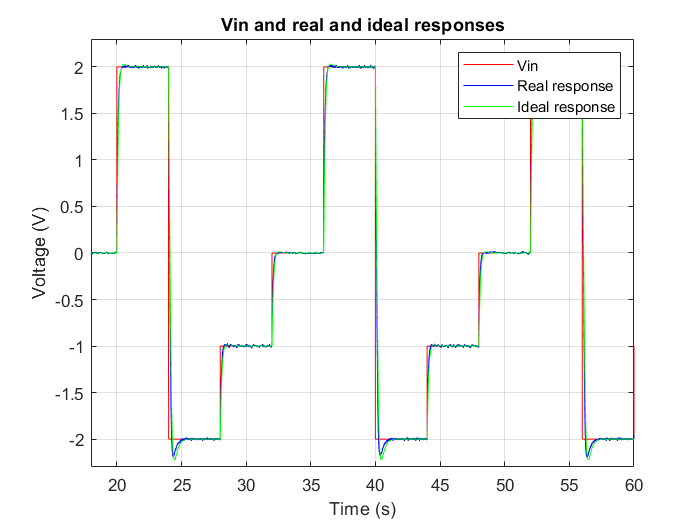

% Draw the motor's response
if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'PIvel']);
    open PI_experimental.slx;
    run PI_experimental.slx;
else
    FileName   = 'PI_real_experimental.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,1,:)],'r')
hold on; grid on;
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,2,:)],'b')
plot(PI_real_experimental.time,[PI_real_experimental.signals.values(:,3,:)],'g')
xlim([18 60]); ylim([-2.3 2.3]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Vin and real and ideal responses');
legend('Vin','Real response','Ideal response');

As it can be analyzed, both answers are practically the same, but if we analyze the desired specifications, we can see that these are not met. This occurs because the PI controller, together with a first-order plant, arise to a closed-loop system with two poles and a zero. The zero, has a negative effect on the dynamics of the system, usually making it a little faster than desired, that is why, in this case we get a small overshoot. In the next practice we will analyze how to eliminate this effect.

# Exercise 12: Design and implementation of a PID controller by pole placement.

Design a PID for the position control that makes the temporary response to a step input present an overshoot of 80% and a oscillation frequency of 0.5 Hz.

To do this, calculate the value of the two dominant poles that meet these specifications and consider a third pole at 0.01. Take the sampling period Ts=0.01s.  Determine the values of $k_p$, $k_i$ and $k_d$ and the 4th pole. Verify if the hypothesis of dominant poles is fulfilled.

% Plant's parameters 
K0=0.82/0.017;
tau0=0.26;
N=9;
Kpot=1.62;

% Sampling time
Ts=0.01;

% Desired control specifications
Sp=80; % overshoot
Fd=0.5; % frequency

% Continuous second order poles that will meet the specifications
wd=2*pi*Fd ;
xi=sqrt((log(Sp/100))^2/(pi^2+log(Sp/100)^2))

xi = 0.0709

wn=wd/ sqrt(1-xi^2)

wn = 3.1495

s1=-xi*wn+j*wd

s1 = -0.2231 + 3.1416i

s2=-xi*wn-j*wd

s2 = -0.2231 - 3.1416i

% Discrete second order poles that will meet the specifications
p1=exp(Ts* s1 )

p1 = 0.9973 + 0.0313i

p2=exp(Ts* s2 )

p2 = 0.9973 - 0.0313i

% Insert the third pole
p3=0.01

p3 = 0.0100

% Discrete plant transfer function 
Ptas=tf([K0*(1/N)*Kpot],[tau0,1,0]);
Ptaz=c2d(Ptas,Ts,'zoh');

% Coefficients of the denominator and enumerator
[Nz ,Dz]= tfdata(Ptaz,'v')

Nz =          0    0.0016    0.0016


Dz =     1.0000   -1.9623    0.9623


a1=Nz(2);
a0=Nz(3);
b1=Dz(2);
b0=Dz(3);

% Definition of matrices A and B
A=[-1 -a1 -a1 -a1 ; p2+p3+p1 a1-a0 -a1-a0 -a0+2*a1 ; ...
   -p1*p2-p3*p1-p2*p3 a0 -a0 2*a0-a1 ; p1*p2*p3 0 0 -a0 ] ;
b=[p1+p2+p3-1+b1 ; -p1*p2-p3*p1-p3*p2+b0-b1 ; p1*p2*p3-b0 ; 0 ] ;

% Controller 
x=inv(A)*b ; 

p4=x(1)

p4 = 0.9475

Kp=x(2)

Kp = 0.3698

Ki=(2/Ts)*x(3)

Ki = 1.5691

Kd=Ts*x(4)

Kd = 0.0580

% Anti-wind-up
pawd=0.2;
Kaw=1/Ki;

% Poles dominance calculation
dominancia=log(abs(p4))/log(abs(p1))

dominancia = 24.1515

The transfer function of the PID has the following form:


$$\textrm{PI}\mathrm{D}\;\mathrm{controller}:\mathrm{P}\textrm{ID}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}+k_d \frac{z-1}{T_{s\;} z}=k_p +k_i^* \frac{z+1}{z-1}+k_d^* \;\frac{z-1}{z}\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}\;\;y\;k_d^* =\frac{k_d }{T_s }$$



$$\mathrm{second}\;\mathrm{order}\;\mathrm{plant}:G\left(z\right)=\frac{a_{1\;} z+a_0 }{z^2 +b_{1\;} z+b_0 }$$


Whereupon the closed loop transfer function takes the form:


$$\mathrm{cl}\left(z\right)=\frac{\mathrm{PID}\left(z\right)G\left(z\right)}{1+\mathrm{PID}\left(z\right)G\left(z\right)}=\frac{\mathrm{Num}\left(z\right)}{\mathrm{Den}\left(z\right)}$$


It can be easily verified that the denominator is:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=z^4 +\left(-1+k_i^* a_1 +b_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(-b_1 -k_p a_1 +k_p a_0 +b_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 +k_d^* a_0 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(k_i^* a_0 -b_0 -2k_d^* a_0 -k_p a_0 +k_d^* a_1 \right)z+k_d^* a_0 
\end{array}$$


The polynomial is of order four, which will have four poles and the characteristic equation will be:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=\left(z-p_1 \right)\left(z-p_2 \right)\left(z-p_3 \right)\left(z-p_4 \right)=z^4 +\left(-p_1 {-p}_2 -p_3 -p_4 \right)z^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \right)z+p_1 p_2 p_3 p_4 
\end{array}$$


As it is a fourth order system and three unknowns, it will not be possible to fix all the poles, being one of them free ($p_4$). The methodology will be acceptable and adequate if the free pole is stable and non-dominant.

By matching the coefficients and representing it in matrix form, the closed loop system would be:


$$\left\lbrack \begin{array}{cccc}
-1 & -a_1  & -a_1  & -a_1 \\
p_1 +p_2 +p_3  & a_1 -a_0  & -a_1 -a_0  & -a_0 +2a_1 \\
-p_1 p_2 -p_3 p_1 -p_3 p_2  & a_0  & -a_0  & 2a_0 -a_1 \\
p_1 p_2 p_3  & 0 & 0 & -a_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p_4 \\
k_p \\
k_i^* \\
k_d^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
p_1 +p_2 +p_3 -1+b_1 \\
-p_1 p_2 -p_3 p_1 -p_3 p_2 +b_0 -b_1 \\
p_1 p_2 p_3 -b_0 \\
0
\end{array}\right\rbrack$$


This linear system is easily solvable using MATLAB. The equation is $A\;x=b$, where $A$ is a matrix $n\;x\;n$ and $b$ is a column vector with $n$ elements, then, $x=\mathrm{inv}\left(A\right)·b$.

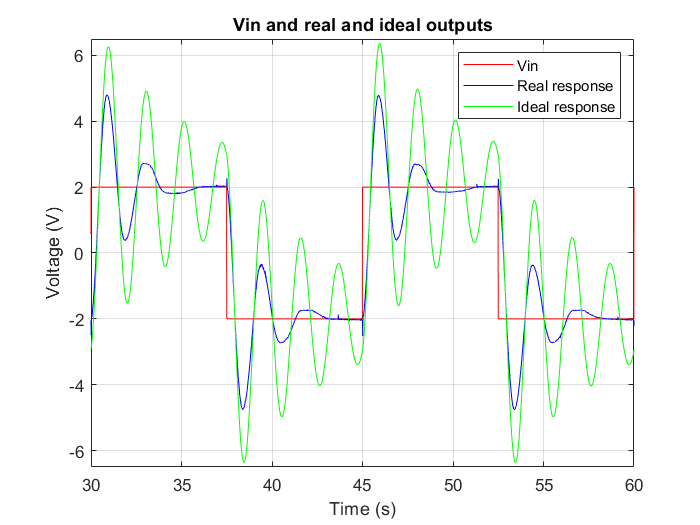

% Draw motor's response
if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'PIvel']);
    open PID_experimental.slx;
    run PID_experimental.slx;
else
    FileName   = 'PID_real_ideal.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,2,:)],'b')
plot(PID_real_ideal.time,[PID_real_ideal.signals.values(:,3,:)],'g')
xlim([30 60]); ylim([-6.5 6.5]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Vin and real and ideal outputs');
legend('Vin','Real response','Ideal response');

As it can be seen, even if the controller is able to establish the system, the real and ideal answers are not similar. This occurs because one of the poles has been set freely and although it complies with the methodology of being free and not dominant, it affects the system. In addition to this, the controller adds two zeros, which also affect the dynamics of the system. Along with all this, we must add the effect that some dynamics have not been modeled.

# Exercise 14: Design the same controllers but with the PID block of Simulink.

Knowing how PID controllers are designed is very important, since we will be able to make a control loop for any system. But in addition to this, we have to know that MATLAB/Simulink offer tools that simplify our work. For example, with the "*pidTuner*" tool we can obtain the gains $k_p$,$\;k_i$ y $k_d$ having only the transfer function of the plant and the desired specifications. By the way, Simulink has a specific block called "*PID Controller*" in which we can specify the gains of each action, the filter coefficient of the derivative part and the sampling period.

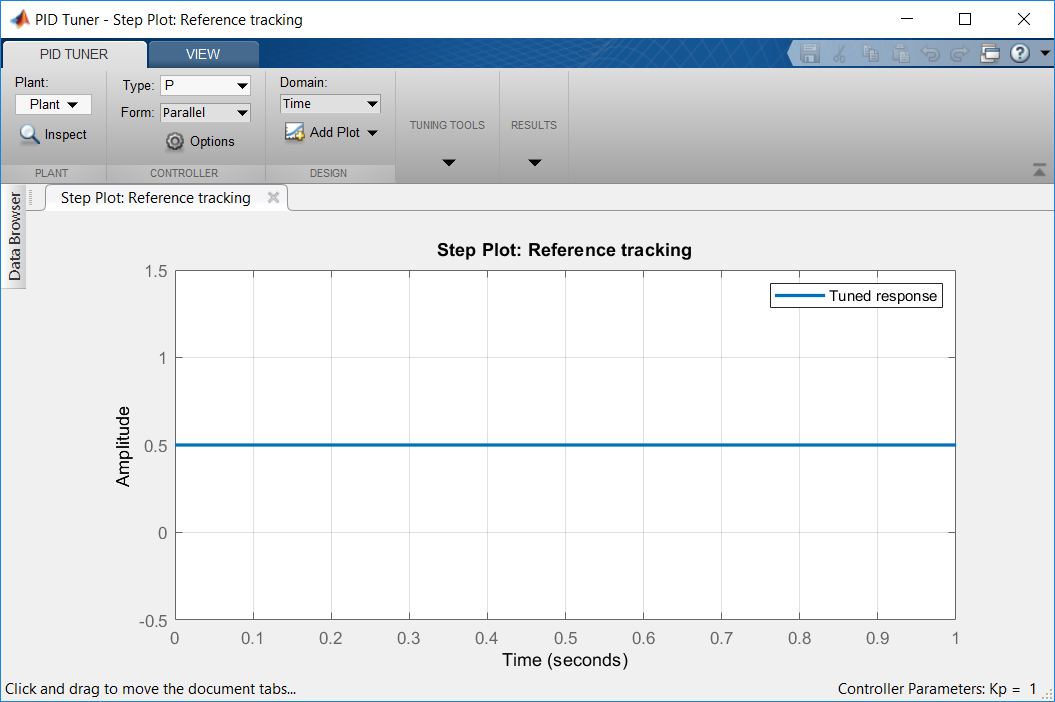

Figure 1: pidTuner tool

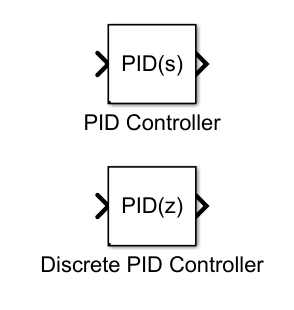

Figure 2: Simulink's PID blocks

In this exercise we want to implement the same controllers, but using this specific block offered by Simulink. For the PI simulation, open and execute the model P3_Ex13a.slx. To execute this model in a plant open and execute the model P3_Ex13b.slx. For the PID simulation, open and execute the model P3_Ex13c.slx and for its verification use the model P3_Ex13d.slx. Analyze that the results obtained in this exercise are equal to the results obtained in the previous exercises.